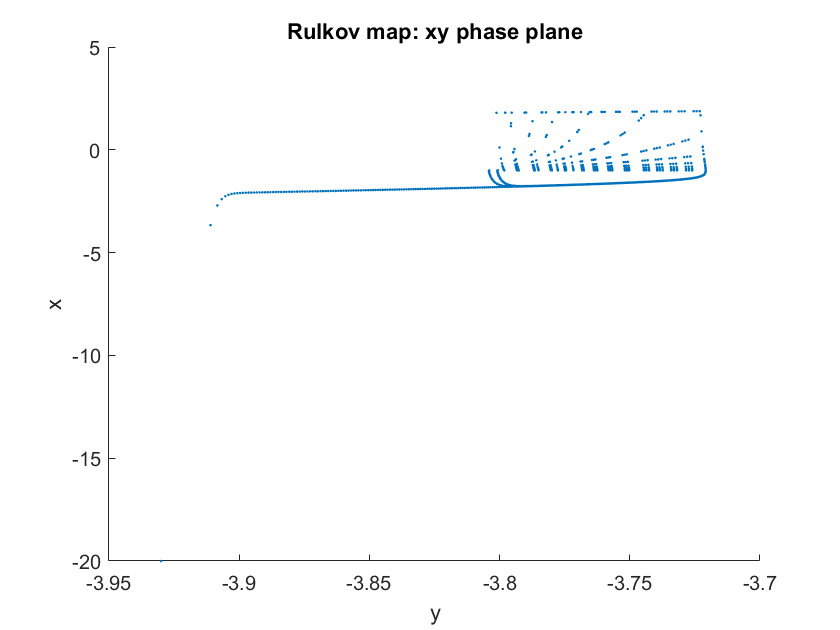

x(1)=-20;
y(1)=-3.93;
a=5.6;
b=0.001;
c=-0.025;
% and now we begin the iteration (10000 iterations):
for n=1:10000
    y(n+1)=y(n) - b*(x(n)-c +1);
        if x(n)<=0
        x(n+1) = (a/(1-x(n)))+y(n);
        elseif x(n)>0 && x(n)<a+y(n)
        x(n+1) = a+y(n);
        else
        x(n+1) = -1;
        end
end
hold on
plot(y(1:9999),x(1:9999),'.','MarkerSize',4)
title('Rulkov map: xy phase plane')
xlabel('y') 
ylabel('x') 
hold off